# Initialization

clc;
clear;
clear all;


## Parameters

m = 1;
g = 9.81;
%%T = 15;
h_desired = 100;

kp = 0.7;
ki = 0.015;
kd = 2.8;

error_prev = 0;
integral = 0;
derivative = 0;

## Time

dt = 0.01;
t = 0:dt:60;


## Initial Conditions

v = 0;
h = 0;
phase = 1;  % 1 = ascent, 2 = descent

## Storage

V = zeros(size(t));
H = zeros(size(t));


## Simulation Loop

for i = 1:length(t)
    % Phase transitions 
    if phase == 1 && h >= 95
        phase = 2; % go to hover

        % Reset PID states 
        integral = 0;
        derivative = 0;
        error_prev = 0;

    elseif phase == 2 && t(i) > 25
        phase = 3;     % start descent after hover time 
        descent_start_time = t(i);   % store time 

        % Reset PID states 
        integral = 0;
        derivative = 0;
        error_prev = 0;

        % Softer gains for landing 
        kp = 0.6;
        ki = 0.01;
        kd = 2.0;
    end  

    % Target selection
    if phase == 1
        h_target = 100;   % go up
    elseif phase == 2
        h_target = 100;   % hover 
    elseif phase == 3
        v_target = -2.5;
    end

    if phase == 3
        error = v_target - v;
    else 
        error = h_target - h;
    end 

    % PID Calculations
    integral = integral + error * dt;
    integral = max(min(integral, 100), -100);
    alpha = 0.8;       % smooth factor (0.7-0.9 works well)
    % Derivative (with spike protection)
    raw_derivative = (error - error_prev)/dt;
    raw_derivative = max(min(raw_derivative, 50), -50);

    derivative = alpha * derivative + (1 - alpha) * raw_derivative;

    % thrust from PID  
    if phase == 3
        T = kp * error + ki * integral + kd * derivative;
    else
        T = kp * error + ki * integral + kd * derivative - 1.5*v;
    end
     
    % Gravity compensation
    T = T + m*g;

    % Limit thrust (very imp.)
    T = max(0, min(T, 30));

    % dynamics
    a = (T - m*g)/m;
    v = v + a*dt;
    h = h + v*dt;

    % Ground conditions
    if h <= 0
        h = 0;
        v = 0;
        break;        
    end

    % store values
    V(i) = v;
    H(i) = h;

    % update previous error 
    error_prev = error;
end


## Plot Results

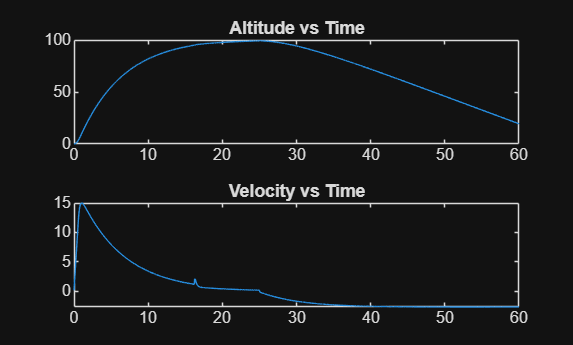

figure;
subplot(2,1,1)
plot(t, H)
title('Altitude vs Time')

subplot(2,1,2)
plot(t, V)
title('Velocity vs Time')

#### Observation:

The motion of the rocket depends on the thrust-to-weight ratio.

When thrust is greater than gravitational force, the rocket accelerates upward.

When thrust is less than gravitational force, the rocket descends.